% N = 5000;
% Fs = 8000;
% load audioclip.mat;
% 
% Fc=50; % cutoff freq
% L=91; % number of coefficients
% n=0:2*L;
% filter_shift = 2*exp(-j*n*12);
% h_LPF_n=2*Fc/Fs*sinc(2*Fc/Fs*(n-L)).*filter_shift;
% H_LPF = fft(h_LPF_n);
% 
% % figure
% % plot(n, abs(h_LPF_n));
% 
% % Frequency domain of the filter
% % H_LPF = fft(h_LPF_n);
% F_filter = -Fs/2:Fs/length(H_LPF):(length(H_LPF)-1)*Fs/(2*length(H_LPF));
% plot(F_filter, fftshift(abs(H_LPF)));


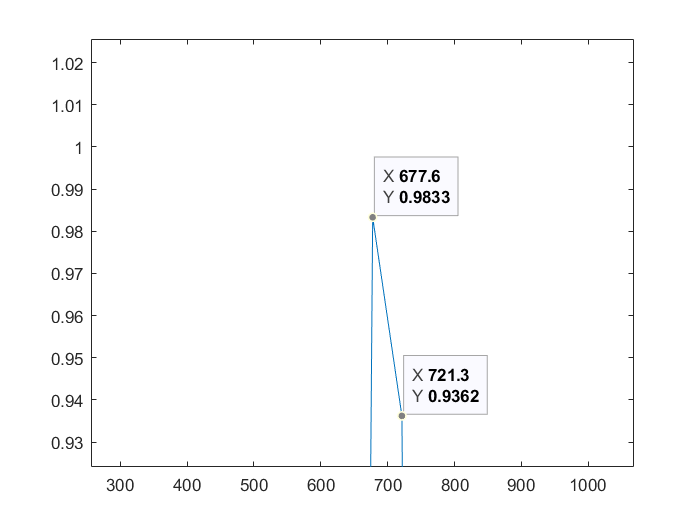

N = 5000;
Fs = 8000;
load audioclip.mat;

Fc1=675; % cutoff freq 1
Fc2=765;
L=91; % number of coefficients
n=0:2*L;
h_LPF_1=2*Fc1/Fs*sinc(2*Fc1/Fs*(n-L));
h_LPF_2=2*Fc2/Fs*sinc(2*Fc2/Fs*(n-L));
h_LPF = h_LPF_2 - h_LPF_1;
H_LPF = fft(h_LPF);
F_filter = -Fs/2:Fs/length(H_LPF):(length(H_LPF)-1)*Fs/(2*length(H_LPF));
plot(F_filter, fftshift(abs(H_LPF)));